# LASSO models with GCP and LeRoy ratios

**Author:** Scott Campit

## Summary

clear all;

## Set up datasets

###  Load intersecting data

% Load raw datasets
load ccle_metabolomics.mat; 
gcp = readtable('MatchingGCPs.xlsx', 'Sheet', 'GCP');

leroy = readtable('MatchingGCPs.xlsx', 'Sheet', 'LeRoy');


% Set up training and test data
leroy_ccls = string(table2array(leroy(:, 'CellLine')));
metabolomics_ccls = string(metabolomics.Properties.RowNames);
gcp_ccls = string(table2array(gcp(:, 'CellLine')));

% Get intersection between GCP and metabolomics
[~, ia, ib] = intersect(metabolomics_ccls, gcp_ccls);
metabolomics = metabolomics(ia, :);
gcp = gcp(ib, :);
metabolomics_ccls = metabolomics_ccls(ia);

% Let's get the indices for cell lines in LeRoy dataset
[~, ix, iy] = intersect(metabolomics_ccls, leroy_ccls);

### Get medium matching CCLs

cellLines2Keep = [          ...
    "HL60", "HUH7", "MCF7", ...
    "NB4", "SW480", "U937"  ...
];

% Get intersection between filtered datasets 
[~, idx] = intersect(table2array(leroy(:, 'CellLine')), cellLines2Keep);
leroy = leroy(idx, :);

[~, idx2] = intersect(metabolomics_ccls, cellLines2Keep);
train_metabolomics = metabolomics(idx2, :);

### Get ratios for histone markers

% Training set
h3k9_ac_me = table2array(leroy(:, 'H3K9ac1')) ./ table2array(leroy(:, ["H3K9me1", "H3K9me2", "H3K9me3"]));
h3k27_ac_me = table2array(leroy(:, 'H3K27ac1')) ./ table2array(leroy(:, ["H3K27me1", "H3K27me2", "H3K27me3"]));
ACME = [h3k9_ac_me, h3k27_ac_me];
ACME(isnan(ACME)) = 0;
ACME(ACME==inf) = max(ACME(isfinite(ACME)));
ACME_ratios = ["H3K9 ac/me1", "H3K9 ac/me2", "H3K9 ac/me3", ...
               "H3K27 ac/me1", "H3K27 ac/me2", "H3K27 ac/me3"];
Xtrain = ACME;

% Test set
h3k9_ac_me = rescale(table2array(gcp(:, 'H3K9ac1'))) ./ rescale(table2array(gcp(:, ["H3K9me1", "H3K9me2", "H3K9me3"])));
h3k27_ac_me = rescale(table2array(gcp(:, 'H3K27ac1'))) ./ rescale(table2array(gcp(:, ["H3K27me1", "H3K27me2", "H3K27me3"])));
GCP_ratios  = [h3k9_ac_me, h3k27_ac_me];
GCP_ratios(isnan(GCP_ratios)) = 0;
GCP_ratios(GCP_ratios==inf) = max(GCP_ratios(isfinite(GCP_ratios)));
GCP_ratio_names = ["H3K9 ac/me1", "H3K9 ac/me2", "H3K9 ac/me3", ...
               "H3K27 ac/me1", "H3K27 ac/me2", "H3K27 ac/me3"];
idx2 = ~ismember(GCP_ratios, GCP_ratios(ix, :));
Xtest = GCP_ratios(idx2(:, 1), :);

### Turn to training and test sets

% Get training and test datasets
Ytrain = double(table2array(train_metabolomics(:, 2:end)));
Ytest = double(table2array(metabolomics(idx2(:, 1), 2:end)));
% Remove rows with NaNs
Ytest(any(isnan(Xtest), 2), :) = [];
Xtest(any(isnan(Xtest), 2), :) = [];
Ytest(any(~isfinite(Xtest), 2), :) = [];
Xtest(any(~isfinite(Xtest), 2), :) = [];

## LASSO model with LeRoy data

for i = 1:size(Ytrain, 2)
    lasso_mdl{i}     = fitrlinear(Xtrain, Ytrain(:, i), ...
                                'Learner', 'leastsquares', ...
                                'Regularization', 'lasso', ...
                                'OptimizeHyperparameters', 'auto', ...
                                'HyperparameterOptimizationOptions', ...
                                     struct('AcquisitionFunctionName', 'expected-improvement-plus', ...
                                            'UseParallel', true, ...
                                            'Verbose', 0, ...
                                            'ShowPlots', false));
end

### Evaluating LASSO Models

#### Cancer cell line metrics

% Row-wise metrics
for j = 1:length(lasso_mdl)
    featMdl = lasso_mdl{j};
    ypred(:, j) = predict(featMdl, Xtest);
end
% Get R, R2, MAE, MSE
for k = 1:size(Ytest, 1)
    covarmat = cov(Ytest(k, :), ypred(k, :));
    corrmat  = corrcov(covarmat);
    pears(k) = corrmat(1, 2); % (1, 2) or (2, 1) will work.
    pr2(k)   = pears(k) .^ 2;
    mae(k)   = sum(abs(Ytest(k, :) - ypred(k, :)), 'all') ./ size(ypred, 1);
    mse(k)   = sum((Ytest(k, :) - ypred(k, :)).^2, 'all') ./ size(ypred, 1);
end
% Get p-value associated with R
for l = 1:length(pears)
    [~, ppval(l)] = ttest2(pears(l), pears);
end
rowmetrics.pearson = pears';  
rowmetrics.pearspval = ppval';
rowmetrics.pearsR2 = pr2';    
rowmetrics.meanAbsSqr = mae'; 
rowmetrics.meanSqrErr= mse';
clear pears ppval pr2 mae mse

#### Metabolite-wise metrics

% Column-wise metrics
for j = 1:length(lasso_mdl)
    featMdl = lasso_mdl{j};
    ypred = predict(featMdl, Xtest);
    [pears(j), ppval(j)] = corr(Ytest(:, j), ypred, 'Type', 'Pearson');
    pr2(j) = pears(j).^2;
    mae(j) = sum(abs(Ytest(:, j) - ypred), 'all') ./ length(ypred);
    mse(j) = sum((Ytest(:, j) -ypred).^2, 'all') ./ length(ypred);
end
colmetrics.pearson = pears';  
colmetrics.pearspval = ppval';
colmetrics.pearsR2 = pr2';    
colmetrics.meanAbsSqr = mae'; 
colmetrics.meanSqrErr = mse';

clear pears ppval pr2 mae mse

#### LASSO coefficients

for j = 1:length(lasso_mdl)
    lasso_coef(j, :) = lasso_mdl{j}.Beta;
end

redbluecmap = imresize(redbluecmap, [1000, 3]); 
redbluecmap = min(max(redbluecmap, 0), 1);
markers = GCP_ratio_names

markers = 1×6 string array
  Columns 1 through 4

    "H3K9 ac/me1"    "H3K9 ac/me2"    "H3K9 ac/me3"    "H3K27 ac/me1"

  Columns 5 through 6

    "H3K27 ac/me2"    "H3K27 ac/me3"


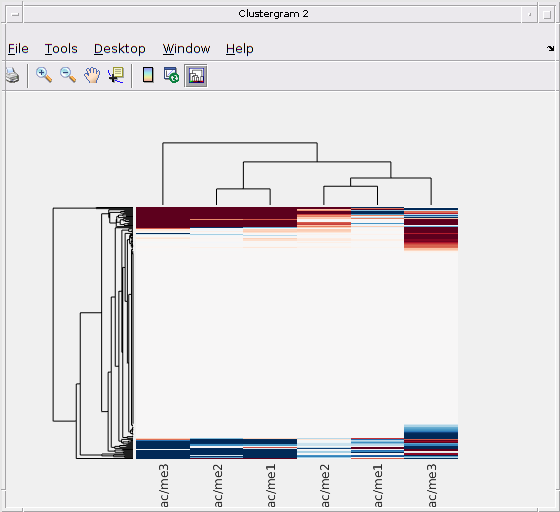

Clustergram object with 225 rows of nodes and 6 columns of nodes.



metabolites = metabolomics.Properties.VariableNames(2:end)';

clustergram(lasso_coef, ...
            'RowLabels', metabolites, ...
            'ColumnLabels', markers, ...
            'RowPdist', 'euclidean', ...
            'ColumnPdist', 'euclidean', ...
            'Colormap', redbluecmap)

## LASSO model with CCLE data

### Create new ratios of histone markers

clear all;

% Load raw datasets
load ccle_metabolomics.mat; 
gcp = readtable('GCP_single.csv');

% Set up training and test data
metabolomics_ccls = string(metabolomics.Properties.RowNames);
gcp_ccls = string(table2array(gcp(:, 'CellLine')));

% Get intersection between GCP and metabolomics
[~, ia, ib] = intersect(metabolomics_ccls, gcp_ccls);
metabolomics = metabolomics(ia, :);
gcp = gcp(ib, :);
metabolomics_ccls = metabolomics_ccls(ia);

### Create the training and test sets

% Data preprocessing
h3k4_ac_me = rescale(table2array(gcp(:, 'H3K4ac1'))) ./ rescale(table2array(gcp(:, ["H3K4me1", "H3K4me2"])));
h3k9_ac_me = rescale(table2array(gcp(:, 'H3K9ac1'))) ./ rescale(table2array(gcp(:, ["H3K9me1", "H3K9me2", "H3K9me3"])));
h3k27_ac_me = rescale(table2array(gcp(:, 'H3K27ac1'))) ./ rescale(table2array(gcp(:, ["H3K27me1", "H3K27me2", "H3K27me3"])));
X = [h3k4_ac_me, h3k9_ac_me, h3k27_ac_me];
X(isnan(X)) = 0;
X(X==inf) = max(X(isfinite(X)));
ACME_ratios = ["H3K4 ac/me1", "H3K4 ac/me2", ...
               "H3K9 ac/me1", "H3K9 ac/me2", "H3K9 ac/me3", ...
               "H3K27 ac/me1", "H3K27 ac/me2", "H3K27 ac/me3"];

Y = double(table2array(metabolomics(:, 2:end)));
% Remove rows with NaNs
Y(any(isnan(X), 2), :) = [];
X(any(isnan(X), 2), :) = [];
Y(any(~isfinite(X), 2), :) = [];
X(any(~isfinite(X), 2), :) = [];

% Create training and test datasets
[Xtrain, Ytrain, Xtest, Ytest] = trainTestSplit(X, Y, 0.8)
        

### Train LASSO models

for i = 1:size(Ytrain, 2)
    lasso_mdl{i}     = fitrlinear(Xtrain, Ytrain(:, i), ...
                                'Learner', 'leastsquares', ...
                                'Regularization', 'lasso', ...
                                'OptimizeHyperparameters', 'auto', ...
                                'HyperparameterOptimizationOptions', ...
                                     struct('AcquisitionFunctionName', 'expected-improvement-plus', ...
                                            'UseParallel', true, ...
                                            'Verbose', 0, ...
                                            'ShowPlots', false));
end

### Evaluating LASSO Models

#### Cancer cell line metrics

% Row-wise metrics
for j = 1:length(lasso_mdl)
    featMdl = lasso_mdl{j};
    ypred(:, j) = predict(featMdl, Xtest);
end
% Get R, R2, MAE, MSE
for k = 1:size(Ytest, 1)
    covarmat = cov(Ytest(k, :), ypred(k, :));
    corrmat  = corrcov(covarmat);
    pears(k) = corrmat(1, 2); % (1, 2) or (2, 1) will work.
    pr2(k)   = pears(k) .^ 2;
    mae(k)   = sum(abs(Ytest(k, :) - ypred(k, :)), 'all') ./ size(ypred, 1);
    mse(k)   = sum((Ytest(k, :) - ypred(k, :)).^2, 'all') ./ size(ypred, 1);
end
% Get p-value associated with R
for l = 1:length(pears)
    [~, ppval(l)] = ttest2(pears(l), pears);
end
rowmetrics.pearson = pears';  
rowmetrics.pearspval = ppval';
rowmetrics.pearsR2 = pr2';    
rowmetrics.meanAbsSqr = mae'; 
rowmetrics.meanSqrErr= mse';
clear pears ppval pr2 mae mse

#### Metabolite-wise metrics

% Column-wise metrics
for j = 1:length(lasso_mdl)
    featMdl = lasso_mdl{j};
    ypred = predict(featMdl, Xtest);
    [pears(j), ppval(j)] = corr(Ytest(:, j), ypred, 'Type', 'Pearson');
    pr2(j) = pears(j).^2;
    mae(j) = sum(abs(Ytest(:, j) - ypred), 'all') ./ length(ypred);
    mse(j) = sum((Ytest(:, j) -ypred).^2, 'all') ./ length(ypred);
end
colmetrics.pearson = pears';  
colmetrics.pearspval = ppval';
colmetrics.pearsR2 = pr2';    
colmetrics.meanAbsSqr = mae'; 
colmetrics.meanSqrErr = mse';

clear pears ppval pr2 mae mse

#### LASSO coefficients

for j = 1:length(lasso_mdl)
    lasso_coef(j, :) = lasso_mdl{j}.Beta;
end

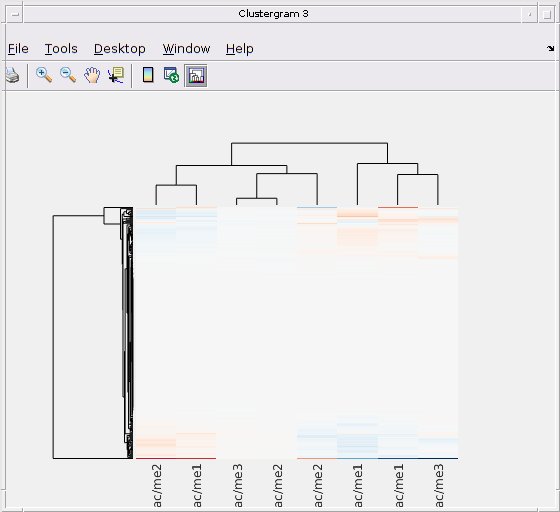

Clustergram object with 225 rows of nodes and 8 columns of nodes.



redbluecmap = imresize(redbluecmap, [1000, 3]); 
redbluecmap = min(max(redbluecmap, 0), 1);
markers = ACME_ratios;
metabolites = metabolomics.Properties.VariableNames(2:end)';

clustergram(lasso_coef, ...
            'RowLabels', metabolites, ...
            'ColumnLabels', markers, ...
            'RowPdist', 'euclidean', ...
            'ColumnPdist', 'euclidean', ...
            'Colormap', redbluecmap)